# Compare Entropy and Information Metrics

This script compares histogram, nearest neighbor, and kernel methods for calculating mutual information.

## Initialize Workspace

% Clear everything:
clear all; close all force; clc;

% Path maintenance:
restoredefaultpath
addpath('matlab_tools')
addpath('project_tools')

% Initialize plotting:
fignum = 0;
colors = grab_plot_colors;


## Step 1: 2-D Normal Distribution

% Choose a correlation [0,1]:
correlation = 0.8;

% Construct the covariance matrix:
R = [1,correlation;correlation,1];  % covariance

% True values of entropy and mutual information
iTrue = -1/2 * log(det(R));
hxTrue = 1/2 * log(2*pi*exp(1)*R(1,1));
hyTrue = 1/2 * log(2*pi*exp(1)*R(2,2));

% Screen report:
fprintf(['True values for 2-D joint Gaussian with R^2 = %1.2f: \n' ...
    '--- Mutual Info:   I(X;Y) = %f [nats] \n' ...
    '--- Entropy of X:  H(X)   = %f [nats] \n' ...
    '--- Entropy of Y:  H(Y)   = %f [nats] \n'],...
    correlation,iTrue,hxTrue,hyTrue);

True values for 2-D joint Gaussian with R^2 = 0.80: 
--- Mutual Info:   I(X;Y) = 0.510826 [nats] 
--- Entropy of X:  H(X)   = 1.418939 [nats] 
--- Entropy of Y:  H(Y)   = 1.418939 [nats] 


## Step 1.1: Convergence of Estimators for 2-D Normal

% Sample sizes to test:
nSampleSizes = 10;      % number of sample sizes
maxSampleSize = 3;      % maximum sample size
sampleSizes = unique(round(logspace(1,maxSampleSize,nSampleSizes)));
nSampleSizes = length(sampleSizes);

% Number of Histogram Bins:
nBinCounts = 5;         % number of sample sizes
maxBinCounts = 2;       % maximum number of bins
binCounts = unique(round(logspace(1,maxBinCounts,nBinCounts)));
nBinCounts = length(binCounts);

% Number of Nearest Neighbors:
nNeighbors = 5;

% Kernel Bandwidths:
nBandwidths = 5;
bandwidths = [linspace(0,1,nBandwidths),-1];
bandwidths(1) = [];

% Initialize storage (nearest neighbors):
ikNN    = zeros(nSampleSizes,nNeighbors)./0;
hxkNN   = zeros(nSampleSizes,nNeighbors)./0;
hykNN   = zeros(nSampleSizes,nNeighbors)./0;

% Initialize storage (histogram estimators):
iHist   = zeros(nSampleSizes,nBinCounts)./0;
hxHist  = zeros(nSampleSizes,nBinCounts)./0;
hyHist  = zeros(nSampleSizes,nBinCounts)./0;

% Initialize storage (histogram estimators):
iKernel  = zeros(nSampleSizes,nBandwidths)./0;
hxKernel = zeros(nSampleSizes,nBandwidths)./0;
hyKernel = zeros(nSampleSizes,nBandwidths)./0;

% Initialize progress bar:
if 1 % container to control screen output
totalCalcs = nSampleSizes * nBinCounts;
timerCalcs = round(linspace(1,totalCalcs,50));
calcCount = 0;
fprintf('Sampling ... \n');
fprintf(strcat(repmat('.',[1,50]),'\n')); tic;
% Loop through sample sizes and bin counts:
for s = 1:nSampleSizes
    
    % Draw a sample:
    sample = randn(sampleSizes(s),2) * chol(R);
    X = sample(:,1);
    Y = sample(:,2);
    
    % Standard histogram method:
    for b = 1:nBinCounts
        [iHist(s,b),hxHist(s,b),hyHist(s,b)] = hist_info(X,Y,binCounts(b));
    end % c-loop
    
    % Nearest neighbors method:
    for k = 1:nNeighbors
        
        % screen report
        calcCount = calcCount + 1;
        if ismember(calcCount,timerCalcs); fprintf('.'); end
        
        % perform calcualtion
        [ikNN(s,k),hxkNN(s,k),hykNN(s,k)] = knn_info(X,Y,k);
        
    end % k-loop
    
    % Kernel density method:
    for h = 1:nBandwidths
        [iKernel(s,h),hxKernel(s,h),hyKernel(s,h)] = kernel_info(X,Y,bandwidths(h));
    end % h-loop
    
end % s-loop

% Screent report:
fprintf('time = %f[s] \n',toc);
end % container for screen report

Sampling ... 


..................................................


..................................................

time = 4.117135[s] 


## Step 1.2: Plot Convergence Results

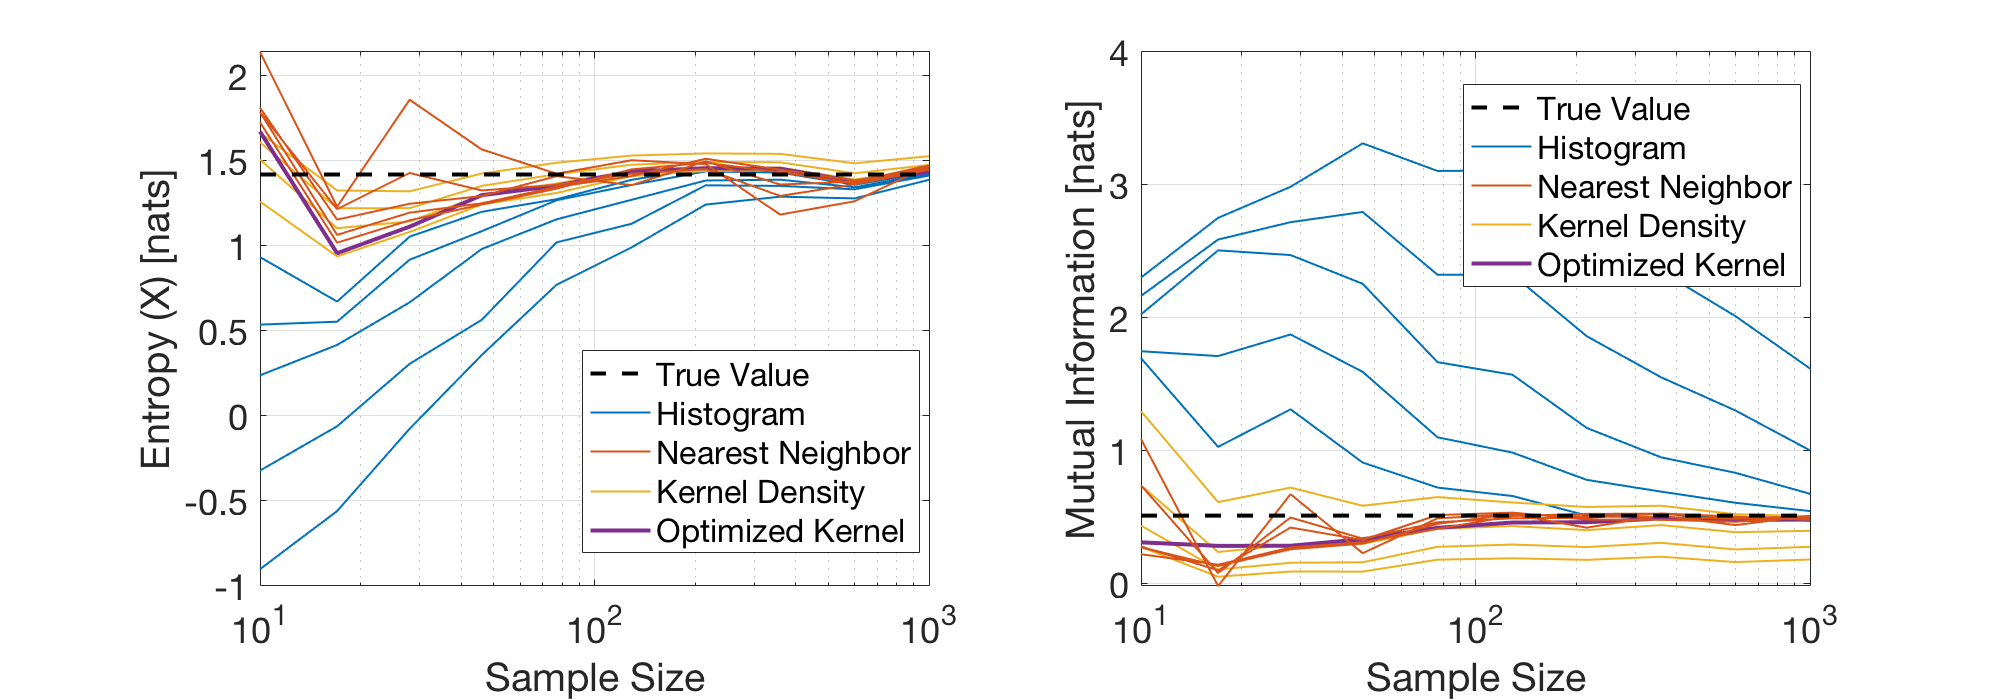

% Initialize a figure for plotting entropy estimates:
fignum = fignum+1; figure(fignum); close(fignum); figure(fignum);
set(gcf,'position',[1,1,1000,350]);

% Plot mutual information values:
subplot(1,2,1)
plotHist        = plot(sampleSizes,hxHist,'color',colors(1,:),'linewidth',1); hold on;
plotKernel      = plot(sampleSizes,hxKernel,'color',colors(3,:),'linewidth',1); hold on;
plotKernelOpt   = plot(sampleSizes,hxKernel(:,end),'color',colors(4,:),'linewidth',2); hold on;
plotkNN         = plot(sampleSizes,hxkNN,'color',colors(2,:),'linewidth',1); hold on;
plotTrue        = plot([nSampleSizes(1),sampleSizes(end)],[hxTrue,hxTrue],'k--','linewidth',2);

% Aesthetics:
set(gca,'Xscale','log')
legend([plotTrue,plotHist(1),plotkNN(1),plotKernel(1),plotKernelOpt],...
    'True Value','Histogram','Nearest Neighbor','Kernel Density','Optimized Kernel',...
    'location','best')
xlabel('Sample Size')
ylabel('Entropy (X) [nats]')
set(gca,'fontsize',18);
grid on;

% Plot mutual information values:
subplot(1,2,2)
plotHist        = plot(sampleSizes,iHist,'color',colors(1,:),'linewidth',1); hold on;
plotKernel      = plot(sampleSizes,iKernel,'color',colors(3,:),'linewidth',1); hold on;
plotKernelOpt   = plot(sampleSizes,iKernel(:,end),'color',colors(4,:),'linewidth',2); hold on;
plotkNN         = plot(sampleSizes,ikNN,'color',colors(2,:),'linewidth',1); hold on;
plotTrue        = plot([nSampleSizes(1),sampleSizes(end)],[iTrue,iTrue],'k--','linewidth',2);

% Aesthetics:
set(gca,'Xscale','log')
legend([plotTrue,plotHist(1),plotkNN(1),plotKernel(1),plotKernelOpt],...
    'True Value','Histogram','Nearest Neighbor','Kernel Density','Optimized Kernel',...
    'location','best')
xlabel('Sample Size')
ylabel('Mutual Information [nats]')
set(gca,'fontsize',18);
grid on;

## Step 2: High-Dimensional Estimation

% How many kernels?
nKernels = 1;

% Which type(s) of kernel to use?
kernelType = 'Normal';

% Choose copula strength:
copulaCovariance = 0.8;

% How many samples?
logSamples = 1.8;
nSamples = round(10^logSamples);

% How many histogram bins?
nBins = 14;

% Create joint densities:
creat_joint_density(nMarginals,nKernels,kernelType,copulaCovariance);

Invalid expression. Check for missing or extra characters.


% The section for sampling and plotting a joint distribution is 
% condensed to a single function to save space in this live script.
fignum = 1;
sample = section_sample_and_plot_joint(jointDensity,nSamples,nBins,fignum);

% % Dimensions of the joint distribution:
% nDims = 6;
% nDimsX = 3;
% nDimsY = nDims - nDimsX;
%
% % Construct the Joint Distribution:
% R = randn(nDims);
% R = R'*R;
% Rx = R(1:nDimsX,1:nDimsX);
% Ry = R(1+nDimsX:end,1+nDimsX:end);
% rho = zeros(nDims)./0;
% for r = 1:nDims
%     rho(r,:) = R(r,:) / sqrt(R(r,r));
% end
% for c = 1:nDims
%     rho(:,c) = rho(:,c) / sqrt(R(c,c));
% end
%
% hxTrue = 1/2 * log((2*pi*exp(1))^nDimsX * det(R(1,1)));
% hyTrue = 1/2 * log((2*pi*exp(1))^nDimsY * det(R(2,2)));
% iTrue = -1/2 * log(det(rho));
